clear
syms theta omega omega_dot_ [3 1] real
% omega is in basis A, which is not the body-fixed basis
P_IA = spinmat([3,2],[theta3,theta2]);
syms l g m
r_bo = [l;0;0]; % basis A or B
F_bG = [0;0;-m*g]; % basis I
syms I_p I_s
I_Bo = diag([I_s I_p I_p]); % basis A or B
omega_AI = omega - [omega1+omega3*tan(theta2);0;0]; % basis A

M_Bo = cross(r_bo,P_IA'*F_bG) == I_Bo*omega_dot_ + cross(omega_AI,I_Bo*omega)

$$M\_Bo = \left[\begin{array}{c} 0=I_{s}\,{\dot{\omega }}_{1}\\ g\,l\,m\,\cos\left(\theta_{2}\right)=I_{p}\,\tan\left(\theta_{2}\right)\,{\omega_{3}}^{2}+I_{s}\,\omega_{1}\,\omega_{3}+I_{p}\,{\dot{\omega }}_{2}\\ 0=I_{p}\,{\dot{\omega }}_{3}-I_{s}\,\omega_{1}\,\omega_{2}-I_{p}\,\omega_{2}\,\omega_{3}\,\tan\left(\theta_{2}\right) \end{array}\right]$$

[A,f] = equationsToMatrix(M_Bo,omega_dot_);
clearvars -except A f theta omega

## Substitute Values:

m = 5;
l = 1;
g = 9.8;

R = 0.5; %disk radius
h = 0.1; %disk depth

theta0 = [0;0;0];
omega0 = [20;1;1];

tf = 5;

%%%%%%%%%%%%%
I_s = (1/2)*m*R^2;
I_p = (1/12)*m*(h^2+3*R^2+12*l^2);

## Integrate:

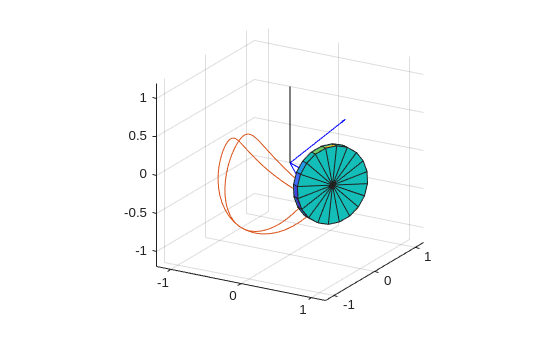

hA = matlabFunction(subs(A),'Vars',{[theta;omega]});
hf = matlabFunction(subs(f),'Vars',{[theta;omega]});
% rates of change of euler angles in terms of those angles and the body
% angular speeds:
hw = @(ang,ome) [1,0,tan(ang(2));0,1,0;0,0,sec(ang(2))]*ome;

% z = [theta;omega]
function z_dot = EOM(z,hw,hA,hf)
theta_dot = hw(z(1:3),z(4:6));
omega_dot = hA(z)\hf(z);
z_dot = [theta_dot;omega_dot];
end

[t,z] = ode45(@(t,z)EOM(z,hw,hA,hf), linspace(0,tf,30*tf),[theta0;omega0]);
z=z';

%Animate:
figure(1)
clf
plot3([0,0],[0,0],[0,l],'k')
hold on
traj = plot3(nan,nan,nan);
axis equal
axis([-1,1,-1,1,-1,1]*1.2*l)
grid on
view([30 20])

disk = hgtransform;
[a,b,c] = cylinder;
surf(h*c-h/2,R*a,R*b,'Parent',disk)
surf(( h/2)*ones(size(c)),[0;R].*a,[0;R].*b,'Parent',disk)
surf((-h/2)*ones(size(c)),[0;R].*a,[0;R].*b,'Parent',disk)

basis = hgtransform;
quiver3([0,0,0],[0,0,0],[0,0,0],[l,0,0],[0,l,0],[0,0,l],'b','Parent',basis)

for i = 1:length(t)
    mat = spinmat([3,2,1],z([3,2,1],i)');
    r_bo = mat*[l;0;0];
    set(disk, 'Matrix',[mat,r_bo;[0,0,0,1]])
    set(basis,'Matrix',[mat,[0;0;0];[0,0,0,1]])
    set(traj,'XData',[traj.XData,r_bo(1)],'YData',[traj.YData,r_bo(2)],'ZData',[traj.ZData,r_bo(3)])
    drawnow
end

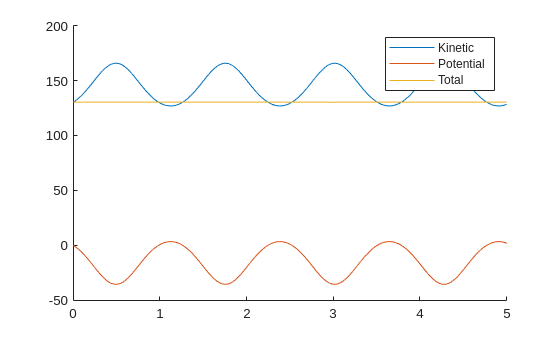

% Check conservation of energy:
I_Bo = diag([I_s,I_p,I_p]);

T = @(i) (1/2)*z(4:6,i)'*I_Bo*z(4:6,i);
V = @(i) -m*g*l*sin(z(2,i));

figure(2)
clf
hold on
plot(t,arrayfun(T,1:length(t)),'DisplayName','Kinetic')
plot(t,arrayfun(V,1:length(t)),'DisplayName','Potential')
plot(t,arrayfun(@(i)T(i)+V(i),1:length(t)),'DisplayName','Total')
legend